# Transfer Learning Paper - 1 (Analysis)

## Data Load

The data is compiled into a single structure file and loaded into 'Data.mat'

## Impact of Coms Range - Summary

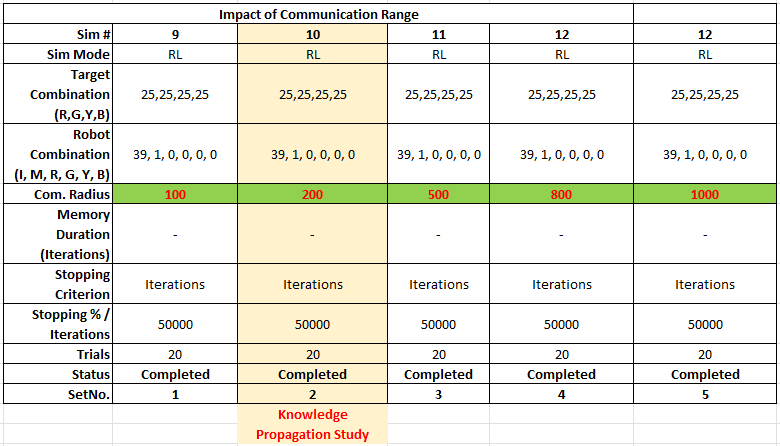

clc
clear all
close all
cd ('D:\Cloud Drives\OneDrive - University of Georgia\Task Learning  - Behavior Trees\KT-BT\Simulation Results');
load('Results.mat')
header={'Iteration',...         %1
        'T-Red Collected',...   %2
        'T- Green Collected',... %3
        'T- Yellow Collected',...	%4
        'T- Blue Collected',...	%5
        'Cur. Lrn Req.',...	%6
        'Cur. Teach Resp.',... %7	
        'Cur. RandomWalk States',...	%8
        'Cur. Target Carry States',...	%9
        'Cum. Lrn. Req.',...	%10
        'Cum. Teach. Resp.',...	%11
        'Direct Learn Cum',...	%12
        'Buf Learn Cum.',...	%13
        'Cum. Pass Learn',...	%14
        'Cum Targets Carried',...	%15
        'Cur. Known St. Red',...	%16
        'Cur. Known St. Green',...	%17
        'Cur. Known St. Yellow',...	%18
        'Cur. Known St. Blue',...	%19
        'Cur. 0 Cond. Known',...	%20
        'Cur. 1 Cond. Known',...	%21
        'Cur. 2 Cond. Known',...	%22
        'Cur. 3 Cond. Known',...	%23
        'Cur. 4 Cond. Known',...     %24
        'RG',... %25
        'RY',... %26
        'RB',... %27
        'GY',... %28
        'GB',... %29
        'YB',... %30
        'RGY',... %31 
        'RGB',... %32
        'RYB',... %33
        'GYB',... %34
        'RGYB',... %35
        
        };   


totTrials=20;
totFields=35;
targetPerc=95;



baseLineData{1}=Results.NoObstaclesBaseLine{1}.NL; % 40 Ms case
baseLineData{2}=Results.NoObstaclesBaseLine{2}.NL; % 10, 10, 10, 10 case
baseLineLength(1)=50000;
baseLineLength(2)=50000;


for st=1:5
    comsRangeData{st}=Results.ComsRange{st}.RL;
    comsRangeLength(st)=50000;
end



for i=1:totTrials
    for st1=1:2
        if(baseLineLength(st1)>length(baseLineData{st1}{i}))
            baseLineLength(st1)=length(baseLineData{st1}{i});
        end
    end

    for st2=1:5
        if(comsRangeLength(st2)>length(comsRangeData{st2}{i}))
            comsRangeLength(st2)=length(comsRangeData{st2}{i});
        end
    end
end



for i=1:totTrials % Trials
    for j=1:totFields
        for st1=1:2
            baseLineFields{st1}{j}(:,i)=baseLineData{st1}{i}(1:baseLineLength(st1),j);
        end
        for st2=1:5
            comsRangeFields{st2}{j}(:,i)=comsRangeData{st2}{i}(1:comsRangeLength(st2),j);
        end
    end
end
for j=1:totFields
    for st1=1:2
        baseLineAvg{st1}(:,j)=mean(baseLineFields{st1}{j},2);
        baseLineStd{st1}(:,j)=std(baseLineFields{st1}{j},0,2);
    end
    for st2=1:5
        comsRangeAvg{st2}(:,j)=mean(comsRangeFields{st2}{j},2);
        comsRangeStd{st2}(:,j)=std(comsRangeFields{st2}{j},0,2);
    end
end
      


for fgsCnt=1:5
    h{fgsCnt}=figure;
end

pltInt=300;
symbls={'p-','*-','^-','s-','d-','h-k','>-'}

symbls = 1×7 cell array
    {'p-'}    {'*-'}    {'^-'}    {'s-'}    {'d-'}    {'h-k'}    {'>-'}


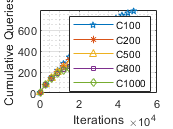

for st2=1:5
    figure(h{1});
    plot(comsRangeAvg{st2}(:,1),comsRangeAvg{st2}(:,10),symbls{st2},'MarkerIndices',1:pltInt:length(comsRangeAvg{st2}),'MarkerSize',5);hold on;
    figure(h{2})
    plot(comsRangeAvg{st2}(:,1),comsRangeAvg{st2}(:,11),symbls{st2},'MarkerIndices',1:pltInt:length(comsRangeAvg{st2}),'MarkerSize',5);hold on;
    figure(h{3});
    plot(comsRangeAvg{st2}(:,1),comsRangeAvg{st2}(:,2)+comsRangeAvg{st2}(:,3)+comsRangeAvg{st2}(:,4)+comsRangeAvg{st2}(:,5),symbls{st2},'MarkerIndices',1:pltInt:length(comsRangeAvg{st2}),'MarkerSize',5);hold on;
    
    figure(h{4})
    plot(comsRangeAvg{st2}(1:end,1),comsRangeAvg{st2}(:,10)-comsRangeAvg{st2}(:,11),symbls{st2},'MarkerIndices',1:pltInt:length(comsRangeAvg{st2}),'MarkerSize',5);hold on;
    
    figure(h{5})
    plot(comsRangeAvg{st2}(1:end-1,1),movmean(diff(comsRangeAvg{st2}(:,10)-comsRangeAvg{st2}(:,11)),1000),symbls{st2},'MarkerIndices',1:pltInt:length(comsRangeAvg{st2}),'MarkerSize',5);hold on;


end

for st1=1:2
%     figure(h{1});
%     plot(baseLineAvg{st1}(:,1),baseLineAvg{st1}(:,10));hold on;
%     figure(h{2})
%     plot(baseLineAvg{st1}(:,1),baseLineAvg{st1}(:,11));hold on;
    figure(h{3});
    plot(baseLineAvg{st1}(:,1),baseLineAvg{st1}(:,2)+baseLineAvg{st1}(:,3)+baseLineAvg{st1}(:,4)+baseLineAvg{st1}(:,5),symbls{st2+st1},'MarkerIndices',1:pltInt:length(comsRangeAvg{st2}),'MarkerSize',5);hold on;
end



figure(h{1});grid on; grid minor; xlabel('Iterations');ylabel('Cumulative Queries');legend({'C100','C200','C500','C800','C1000'},'Location','southeast')

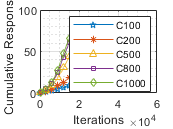

figure(h{2});grid on; grid minor; xlabel('Iterations');ylabel('Cumulative Responses');legend({'C100','C200','C500','C800','C1000'},'Location','southeast')

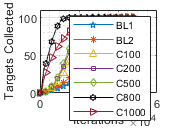

figure(h{3});grid on; grid minor; xlabel('Iterations');ylabel('Targets Collected');legend({'BL1','BL2','C100','C200','C500','C800','C1000'},'Location','southeast');ylim([0 110])

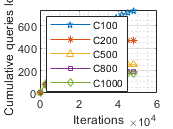

figure(h{4});grid on; grid minor; xlabel('Iterations');ylabel('Cumulative queries lost');legend({'C100','C200','C500','C800','C1000'},'Location','northwest')

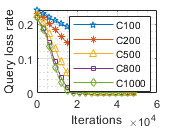

figure(h{5});grid on; grid minor; xlabel('Iterations');ylabel('Query loss rate');legend({'C100','C200','C500','C800','C1000'},'Location','northeast')

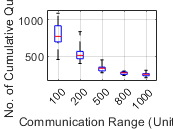

for st2=1:5
    comsRange_CumQueriesFinalAvg(st2)=comsRangeAvg{st2}(end,10);
    comsRange_CumRespFinalAvg(st2)=comsRangeAvg{st2}(end,11);
    comsRange_CumQueriesFinalStd(st2)=comsRangeStd{st2}(end,10);
    comsRange_CumRespFinalStd(st2)=comsRangeStd{st2}(end,11);
    comsRange_CumQueriesFinalDiffAvg(st2)=comsRange_CumQueriesFinalAvg(st2)-comsRange_CumRespFinalAvg(st2);
    comsRange_CumQueriesFinalDiffStd(st2)=sqrt(comsRange_CumQueriesFinalStd(st2).^2+comsRange_CumRespFinalStd(st2).^2);
end


for st2=1:5
    comsRange_CumQueriesFinal(:,st2)=comsRangeFields{st2}{10}(end,:)';
    comsRange_CumRespFinal(:,st2)=comsRangeFields{st2}{11}(end,:)';
    
    
end
comsRange_CumQueriesFinalDiff=comsRange_CumQueriesFinal-comsRange_CumRespFinal;

k1=figure;
boxplot(comsRange_CumQueriesFinal,'whisker',3,'Labels',{'100','200','500','800','1000'},'Widths',0.3);grid on; xlabel('Communication Range (Units)');ylabel('No. of Cumulative Queries');

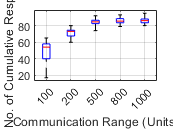

k2=figure;
boxplot(comsRange_CumRespFinal,'whisker',3,'Labels',{'100','200','500','800','1000'},'Widths',0.3);grid on; xlabel('Communication Range (Units)');ylabel('No. of Cumulative Responses');

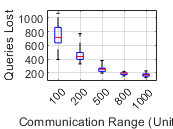

k3=figure;
boxplot(comsRange_CumQueriesFinalDiff,'whisker',3,'Labels',{'100','200','500','800','1000'},'Widths',0.3);grid on; xlabel('Communication Range (Units)');ylabel('Queries Lost');

#### Inference

1.   

2.   

Comments

Add baseline with obstacles.